**Analyse descristipe et statistique des données cas par cas**

%% Comparaison des données qualitatives et quantitatives des patients PreOP vs PostOP %%


%% 1. Extraction des données
% Extraction des colonnes depuis Analysecasparcas
Douleur_Pre = KINetdouleurprevspost(:,1);
Douleur_Post = KINetdouleurprevspost(:,2);
HT_Max_Pre = KINetdouleurprevspost(:,4);
HT_Range_Pre = KINetdouleurprevspost(:,5);
HT_Max_Post = KINetdouleurprevspost(:,7);
HT_Range_Post = KINetdouleurprevspost(:,8);

% Calcul des deltas (différences post-pré)
Delta_Douleur = Douleur_Post - Douleur_Pre;
Delta_Max = HT_Max_Post - HT_Max_Pre;
Delta_Range = HT_Range_Post - HT_Range_Pre;

% Création d'une matrice des paires pré-post pour faciliter l'analyse
data_Pre = [Douleur_Pre, HT_Max_Pre, HT_Range_Pre];
data_Post = [Douleur_Post, HT_Max_Post, HT_Range_Post];
delta_data = [Delta_Douleur, Delta_Max, Delta_Range];
var_names = {'Douleur', 'HT Max', 'HT Range'};

%% 2. Analyse descriptive
% Création d'une table de statistiques descriptives
fprintf('=== Statistiques descriptives ===\n\n');

=== Statistiques descriptives ===



for i = 1:3
    fprintf('--- %s ---\n', var_names{i});
    fprintf('Pré-opératoire  : Moyenne = %.2f, Écart-type = %.2f, Médiane = %.2f\n', ...
        mean(data_Pre(:,i)), std(data_Pre(:,i)), median(data_Pre(:,i)));
    fprintf('Post-opératoire : Moyenne = %.2f, Écart-type = %.2f, Médiane = %.2f\n', ...
        mean(data_Post(:,i)), std(data_Post(:,i)), median(data_Post(:,i)));
    fprintf('Delta (Post-Pré): Moyenne = %.2f, Écart-type = %.2f, Médiane = %.2f\n\n', ...
        mean(delta_data(:,i)), std(delta_data(:,i)), median(delta_data(:,i)));
end

--- Douleur ---


Pré-opératoire  : Moyenne = 3.49, Écart-type = 2.12, Médiane = 3.25


Post-opératoire : Moyenne = 0.83, Écart-type = 1.76, Médiane = 0.00


Delta (Post-Pré): Moyenne = -2.66, Écart-type = 2.26, Médiane = -3.00



--- HT Max ---


Pré-opératoire  : Moyenne = 35.50, Écart-type = 18.38, Médiane = 29.00


Post-opératoire : Moyenne = 60.90, Écart-type = 17.99, Médiane = 66.00


Delta (Post-Pré): Moyenne = 25.40, Écart-type = 19.69, Médiane = 27.50



--- HT Range ---


Pré-opératoire  : Moyenne = 25.05, Écart-type = 14.71, Médiane = 18.50


Post-opératoire : Moyenne = 43.45, Écart-type = 14.99, Médiane = 45.00


Delta (Post-Pré): Moyenne = 18.40, Écart-type = 15.03, Médiane = 19.50




%% 3. Test de normalité des différences (requis pour test t apparié)
fprintf('=== Tests de normalité (Shapiro-Wilk) sur les deltas ===\n');

=== Tests de normalité (Shapiro-Wilk) sur les deltas ===


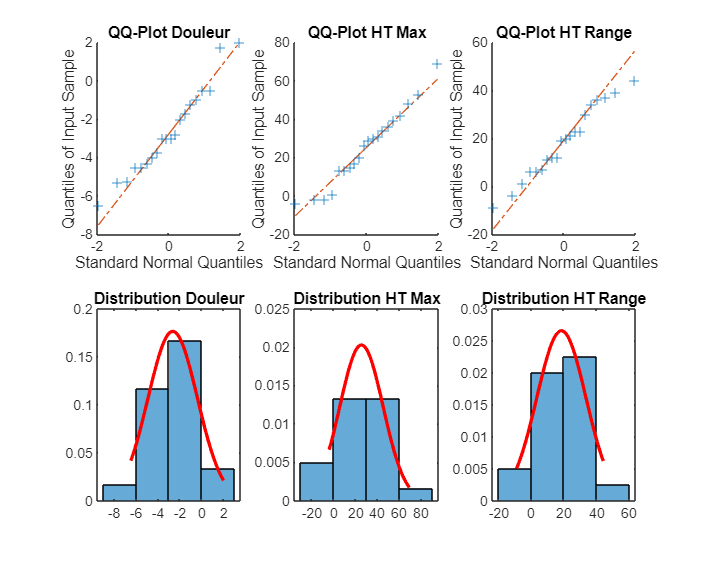

 - Douleur : p = 0.5000, Distribution suit une loi normale


 - HT Max : p = 0.5000, Distribution suit une loi normale


 - HT Range : p = 0.5000, Distribution suit une loi normale


figure('Name', 'Test de normalité des différences', 'Position', [100,100,1000,800]);
for i = 1:3
    % QQ-Plot pour visualiser la normalité
    subplot(2,3,i);
    qqplot(delta_data(:,i));
    title(['QQ-Plot ' var_names{i}]);
    
    % Histogramme avec courbe de densité normale
    subplot(2,3,i+3);
    histogram(delta_data(:,i), 'Normalization', 'pdf');
    hold on;
    x = linspace(min(delta_data(:,i)), max(delta_data(:,i)), 100);
    mu = mean(delta_data(:,i));
    sigma = std(delta_data(:,i));
    y = normpdf(x, mu, sigma);
    plot(x, y, 'r-', 'LineWidth', 2);
    title(['Distribution ' var_names{i}]);
    hold off;
    
    % Test de Shapiro-Wilk pour la normalité
    [H, pValue] = swtest(delta_data(:,i), 0.05);
    normalite = ~H; % H=0 signifie que l'hypothèse de normalité n'est pas rejetée
    
    fprintf(' - %s : p = %.4f, Distribution %s normale\n', ...
        var_names{i}, pValue, conditional(normalite, 'suit une loi', 'ne suit PAS une loi'));
end

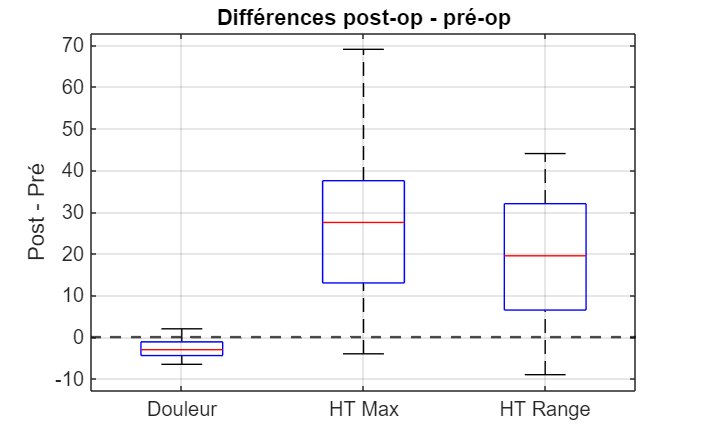

fprintf('\n');

%% 4. Visualisations des données
% Boxplots des deltas
figure('Name', 'Comparaisons Pré/Post (Delta)', 'Position', [100,100,800,500]);
boxplot(delta_data, 'Labels', var_names);
ylabel('Post - Pré');
title('Différences post-op - pré-op');
ax = gca; ax.FontSize = 12;
hold on; 
yline(0, '--k', 'LineWidth', 1.5);
grid on;

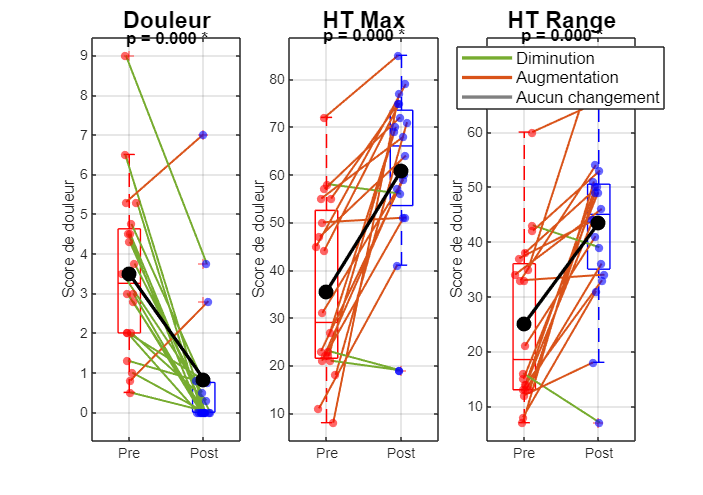


% Boxplots
figure('Name', 'Comparaison Pré vs Post (données appariées)', 'Position', [100,100,1200,900]);
for i = 1:3
    subplot(1,3,i);
    boxplot([data_Pre(:,i), data_Post(:,i)], ...
        'Labels', {'Pré', 'Post'}, 'Colors', 'rb');
    ylabel('Score de douleur')
    hold on;
    set(gcf, 'Color', 'w');
    
    % Jitter pour éviter les superpositions
    jitter_pre = 1 + randn(length(data_Pre), 1)*0.05;
    jitter_post = 2 + randn(length(data_Post), 1)*0.05;
    
    % Couleurs pour les lignes selon l'évolution: vert pour amélioration (diminution douleur),
    % rouge pour détérioration (augmentation douleur)
    for j = 1:length(data_Pre)
        % Détermine si la valeur augmente ou diminue
        if data_Post(j,i) > data_Pre(j,i)
            lineColor = [0.8500, 0.3250, 0.0980, 0.6];  % Rouge-orangé pour augmentation (détérioration)
        elseif data_Post(j,i) < data_Pre(j,i)
            lineColor = [0.4660, 0.6740, 0.1880, 0.6];  % Vert pour diminution (amélioration)
        else
            lineColor = [0.5, 0.5, 0.5, 0.4];  % Gris pour aucun changement
        end
        
        % Dessine la ligne avec la couleur appropriée
        plot([jitter_pre(j), jitter_post(j)], [data_Pre(j,i), data_Post(j,i)], ...
            '-', 'Color', lineColor, 'LineWidth', 1.2);
    end
    
    % Points individuels rouges (Pré) et bleus (Post)
    scatter(jitter_pre, data_Pre(:,i), 25, 'r', 'filled', 'MarkerFaceAlpha', 0.6);
    scatter(jitter_post, data_Post(:,i), 25, 'b', 'filled', 'MarkerFaceAlpha', 0.6);
    
    % Moyennes en noir
    scatter(1, mean(data_Pre(:,i), 'omitnan'), 80, 'k', 'filled');
    scatter(2, mean(data_Post(:,i), 'omitnan'), 80, 'k', 'filled');
    
    % Relier les moyennes
    plot([1, 2], [mean(data_Pre(:,i), 'omitnan'), mean(data_Post(:,i), 'omitnan')], ...
        'k-', 'LineWidth', 2);
    
    % Ajout de la valeur p à chaque graphique
    [~, p_value] = ttest(data_Pre(:,i), data_Post(:,i));
    if p_value < 0.05
        significance = ' *';
    elseif p_value < 0.01
        significance = ' **';
    elseif p_value < 0.001
        significance = ' ***';
    else
        significance = ' (ns)';
    end
    
    text(1.5, max([data_Pre(:,i); data_Post(:,i)])*1.05, ['p = ' num2str(p_value, '%.3f') significance], ...
        'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    
    % Ajouter une légende
    if i == 3  % Ajoute la légende seulement dans le dernier graphique
        h1 = plot(NaN, NaN, '-', 'Color', [0.4660, 0.6740, 0.1880, 0.9], 'LineWidth', 2);
        h2 = plot(NaN, NaN, '-', 'Color', [0.8500, 0.3250, 0.0980, 0.9], 'LineWidth', 2);
        h3 = plot(NaN, NaN, '-', 'Color', [0.5, 0.5, 0.5, 0.9], 'LineWidth', 2);
        legend([h1, h2, h3], {'Diminution', 'Augmentation', 'Aucun changement'}, ...
            'Location', 'best', 'FontSize', 10);
    end
    
    % Titre et axes
    title(var_names{i}, 'FontSize', 14);
    xticks([1 2]);
    xticklabels({'Pre', 'Post'});
    grid on;
    hold off;
end


%% 5. Tests statistiques
fprintf('=== Tests statistiques (Pré vs Post) ===\n\n');

=== Tests statistiques (Pré vs Post) ===




% Pour chaque variable, choisir le test approprié selon la normalité
for i = 1:3
    [H_sw, p_sw] = swtest(delta_data(:,i), 0.05);
    normalite = ~H_sw;
    
    if normalite
        % Test t apparié si les différences suivent une loi normale
        [h, p_value, ci, stats] = ttest(data_Pre(:,i), data_Post(:,i));
        test_type = 'Test t apparié';
        t_val = stats.tstat;
        df = stats.df;
        test_stat = sprintf('t(%d) = %.2f', df, t_val);
    else
        % Test de Wilcoxon (non paramétrique) si non-normalité
        [p_value, h, stats] = signrank(data_Pre(:,i), data_Post(:,i));
        test_type = 'Test de Wilcoxon (signed-rank)';
        test_stat = sprintf('Z = %.2f', stats.zval);
    end
    
    % Taille d'effet
    cohen_d = (mean(data_Post(:,i)) - mean(data_Pre(:,i))) / ...
              std(delta_data(:,i));
    
    % Rapport des résultats
    fprintf('--- %s ---\n', var_names{i});
    fprintf('Test utilisé: %s (normalité: p = %.4f)\n', test_type, p_sw);
    fprintf('Pré: M = %.2f, ET = %.2f; Post: M = %.2f, ET = %.2f\n', ...
        mean(data_Pre(:,i)), std(data_Pre(:,i)), ...
        mean(data_Post(:,i)), std(data_Post(:,i)));
    fprintf('Résultat: %s, p = %.4f', test_stat, p_value);
    
    % Interprétation
    if p_value < 0.05
        fprintf(' (significatif)\n');
        direction = conditional(mean(delta_data(:,i)) > 0, 'augmentation', 'diminution');
        fprintf('Interprétation: %s significative entre pré et post-opératoire\n', direction);
    else
        fprintf(' (non significatif)\n');
        fprintf('Interprétation: Pas de différence significative entre pré et post-opératoire\n');
    end
    
    fprintf('Taille d''effet: d de Cohen = %.2f (%s)\n\n', cohen_d, interpretCohenD(cohen_d));
end

--- Douleur ---


Test utilisé: Test t apparié (normalité: p = 0.5000)


Pré: M = 3.49, ET = 2.12; Post: M = 0.83, ET = 1.76


Résultat: t(19) = 5.25, p = 0.0000

 (significatif)


Interprétation: diminution significative entre pré et post-opératoire


Taille d'effet: d de Cohen = -1.17 (effet fort)



--- HT Max ---


Test utilisé: Test t apparié (normalité: p = 0.5000)


Pré: M = 35.50, ET = 18.38; Post: M = 60.90, ET = 17.99


Résultat: t(19) = -5.77, p = 0.0000

 (significatif)


Interprétation: augmentation significative entre pré et post-opératoire


Taille d'effet: d de Cohen = 1.29 (effet fort)



--- HT Range ---


Test utilisé: Test t apparié (normalité: p = 0.5000)


Pré: M = 25.05, ET = 14.71; Post: M = 43.45, ET = 14.99


Résultat: t(19) = -5.47, p = 0.0000

 (significatif)


Interprétation: augmentation significative entre pré et post-opératoire


Taille d'effet: d de Cohen = 1.22 (effet fort)




%% 6. Tableau récapitulatif pour publication
% Création d'une table organisée pour rapporter les résultats
results_table = table;
results_table.Variable = var_names';
results_table.Pre_Mean = mean(data_Pre)';
results_table.Pre_SD = std(data_Pre)';
results_table.Post_Mean = mean(data_Post)';
results_table.Post_SD = std(data_Post)';
results_table.Delta_Mean = mean(delta_data)';
results_table.Delta_SD = std(delta_data)';
results_table.P_Value = zeros(3,1);
results_table.Effect_Size = zeros(3,1);

for i = 1:3
    [~, p] = ttest(data_Pre(:,i), data_Post(:,i));
    results_table.P_Value(i) = p;
    results_table.Effect_Size(i) = (mean(data_Post(:,i)) - mean(data_Pre(:,i))) / std(delta_data(:,i));
end

% Affichage du tableau récapitulatif
disp('=== Tableau récapitulatif pour publication ===');

=== Tableau récapitulatif pour publication ===


disp(results_table);

      Variable      Pre_Mean    Pre_SD    Post_Mean    Post_SD    Delta_Mean    Delta_SD     P_Value      Effect_Size
    ____________    ________    ______    _________    _______    __________    ________    __________    ___________

    {'Douleur' }      3.49      2.1165     0.8325      1.7644      -2.6575        2.264     4.5691e-05      -1.1738  
    {'HT Max'  }      35.5       18.38       60.9      17.985         25.4       19.685     1.4667e-05       1.2903  
    {'HT Range'}     25.05      14.713      43.45      14.986         18.4       15.035     2.7941e-05       1.2238  




% Enregistrement du tableau pour Excel/publication
writetable(results_table, 'resultats_pre_post.xlsx');

%% Fonction utilitaire pour interpréter la taille d'effet d de Cohen
function interpretation = interpretCohenD(d)
    d_abs = abs(d);
    if d_abs < 0.2
        interpretation = 'effet négligeable';
    elseif d_abs < 0.5
        interpretation = 'effet faible';
    elseif d_abs < 0.8
        interpretation = 'effet moyen';
    else
        interpretation = 'effet fort';
    end
end

%% Fonction utilitaire pour le conditionnel
function result = conditional(condition, if_true, if_false)
    if condition
        result = if_true;
    else
        result = if_false;
    end
end

%% Fonction pour le test Shapiro-Wilk
function [H, pValue] = swtest(x, alpha)
    % SWTEST Test de Shapiro-Wilk pour tester la normalité
    % Note: Cette fonction est une version simplifiée; dans un script réel,
    % utilisez la fonction complète disponible sur MATLAB File Exchange
    
    % Si Stats Toolbox est disponible
    if license('test', 'Statistics_Toolbox')
        % Utilisez le test de Shapiro-Wilk de la toolbox
        [H, pValue] = lillietest(x, 'Distribution', 'normal');
    else
        % Sinon, utilisez une approximation par le test de Jarque-Bera
        n = length(x);
        x = x - mean(x);
        s = std(x);
        if s == 0
            H = true;
            pValue = 0;
            return;
        end
        x = x/s;
        
        skewness = mean(x.^3);
        kurtosis = mean(x.^4) - 3;
        
        JB = n/6 * (skewness^2 + kurtosis^2/4);
        pValue = 1 - chi2cdf(JB, 2);
        H = (pValue < alpha);
    end
end

%% 7. Analyse par groupes basés sur la douleur
fprintf('Groupes manuels de taille équilibrée ===\n\n');

Groupes manuels de taille équilibrée ===




% Trier les valeurs de douleur
[douleur_sorted, douleur_idx] = sort(Douleur_Pre);

% Diviser en groupes de taille équilibrée (2-3 sujets)
n_sujets = length(Douleur_Pre);
sujets_par_groupe = ceil(n_sujets / 4); % ~2-3 sujets par groupe avec 10 sujets
groupe_manuel_id = zeros(size(Douleur_Pre));

for i = 1:n_sujets
    groupe_manuel_id(douleur_idx(i)) = ceil(i/sujets_par_groupe);
end

% Afficher la composition des nouveaux groupes
fprintf('Composition des groupes manuels:\n');

Composition des groupes manuels:


for g = 1:4
    group_idx = (groupe_manuel_id == g);
    fprintf('Groupe %d (n=%d): Valeurs de douleur = ', g, sum(group_idx));
    fprintf('%.1f ', Douleur_Pre(group_idx));
    fprintf('\n');
    fprintf('Moyenne du groupe = %.1f ', mean(Douleur_Pre(group_idx)));
end

Groupe 1 (n=5): Valeurs de douleur = 

2.0 1.0 1.3 0.8 0.5 

Moyenne du groupe = 1.1 

Groupe 2 (n=5): Valeurs de douleur = 

3.0 2.8 2.0 2.0 3.0 

Moyenne du groupe = 2.6 

Groupe 3 (n=5): Valeurs de douleur = 

3.5 4.3 4.5 4.5 3.8 

Moyenne du groupe = 4.1 

Groupe 4 (n=5): Valeurs de douleur = 

5.3 6.5 5.3 4.8 9.0 

Moyenne du groupe = 6.2 

fprintf('\n');